## Import linear model Pod elevation

Elevation_pod_model ='Pod_elev_plant_linear';
io(1)=linio('Pod_elev_plant_linear/Engine_current_input',1,'input');
io(2)=linio('Pod_elev_plant_linear/Gyro_out_switch',1,'output');
simulation_POD_Elevation_plant_to_gyro = linearize(Elevation_pod_model,io);
load('Notch_gain_POD_elev.mat')
load('POD_Elev_PI.mat')

## bode of the original plants

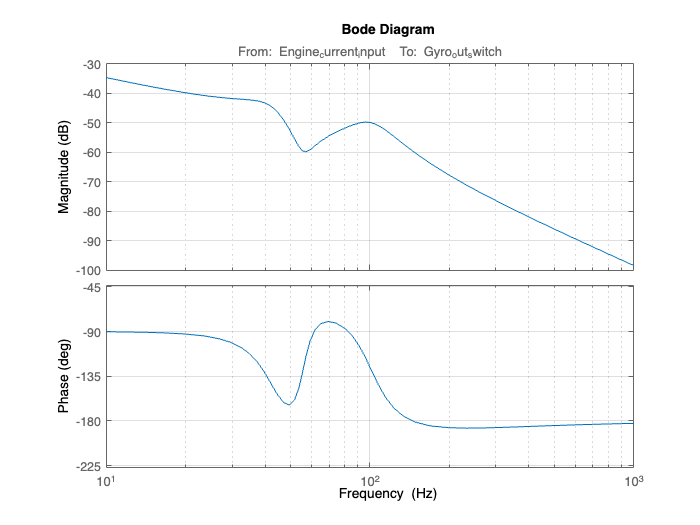

bode(simulation_POD_Elevation_plant_to_gyro)
grid on

## Sisotool for notch filters and gain (external window GUI)

%sisotool(simulation_POD_Elevation_plant_to_gyro)

## Gain and notch

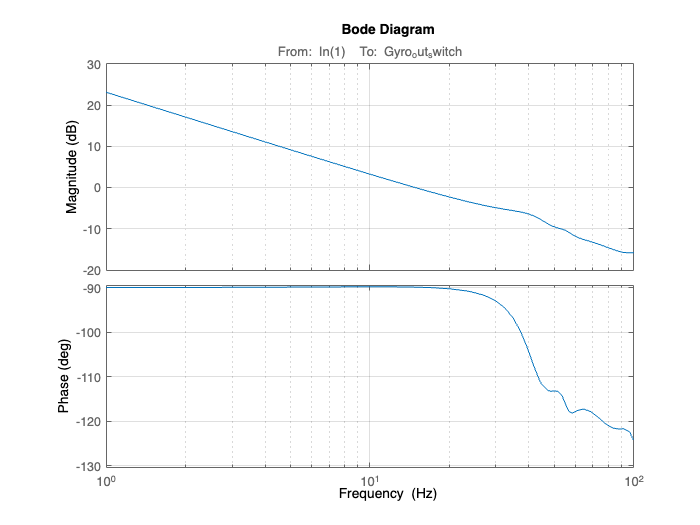

bode(simulation_POD_Elevation_plant_to_gyro*Notch_gain_POD_elev)
grid on
xlim([1,100]);

## PI tuner

opts = pidtuneOptions('PhaseMargin',50);
[C_pi_pod_elev,info] = pidtune(simulation_POD_Elevation_plant_to_gyro*Notch_gain_POD_elev,'PI',130,opts)

C_pi_pod_elev =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 1.03, Ki = 111
 
Continuous-time PI controller in parallel form.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 130
           PhaseMargin: 50.0000


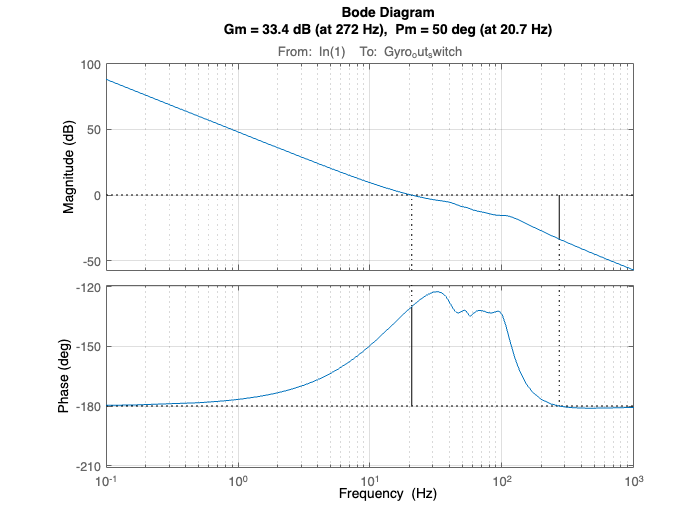

margin(simulation_POD_Elevation_plant_to_gyro*Notch_gain_POD_elev*C_pi_pod_elev)
grid on

## Saved results load

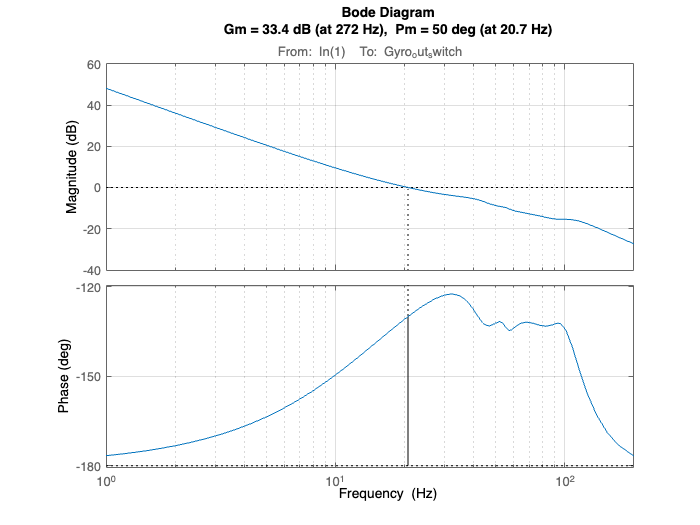

margin(simulation_POD_Elevation_plant_to_gyro*Notch_gain_POD_elev*C_pi_pod_elev)
xlim([1,200])
grid on

## Define transfer function

gain_notch_pod_elev_tf=tf(Notch_gain_POD_elev)

gain_notch_pod_elev_tf =
 
  114.3 s^4 + 4.047e04 s^3 + 5.373e07 s^2 + 7.637e09 s + 3.46e12
  --------------------------------------------------------------
       s^4 + 650 s^3 + 5.092e05 s^2 + 9.179e07 s + 4.326e10
 
Name: C
Continuous-time transfer function.



C_pi_pod_elev_Kp=C_pi_pod_elev.Kp+0.06; 